# dinteg_ddi

performs the integral double of a sampled signal with the de-drifted integration (DDI method) 

## Syntax

pos=dinteg_ddi(acc,freq)

## Description

`pos=dinteg_ddi(acc,freq)` performs the integral double of a signal `acc` sampled at `freq` Hz with the the optimally filtered integration (OFI method). 

It encompasses the subtraction of a weighted mean function of data samples, previous to each of both integrations. The acceleration drift function is computed by averaging a few initial and final accelerometry samples and by removing a lineal interpolation between both values from the original signal. The size of both sets of samples is empirically selected. 		

	  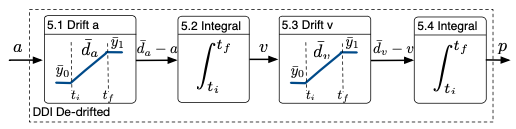		

The velocity drift function is based on the assumption of zero velocity at the beginning and end of the cycle, and a lineal function from zero to the mean of the last velocity samples is subtracted from to achieve it. 

More information: 

Rampp, A.; Barth, J.; Schuelein, S.; Gassmann, K.G.; Klucken, J.; Eskofier, B.M. Inertial Sensor-Based 							Stride Parameter Calculation From Gait Sequences in Geriatric Patients. *IEEE Trans. Biomed. Eng. ***2015**, 							*62*, 1089–1097. 												

## Examples

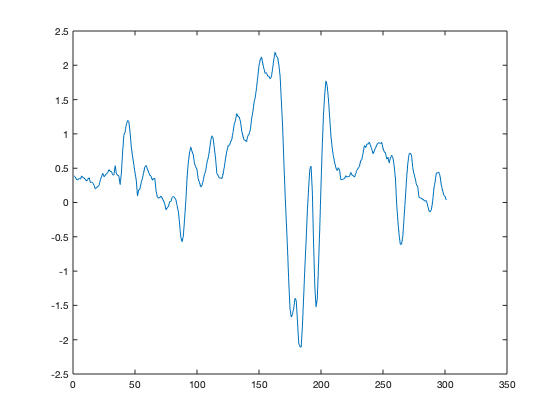

% cargamos datos de una acelerometro que sube y vuelve a la posicion de
% reposo:
filename='../simur_data/SAL.log';
datosxs=load(filename);
acc=datosxs(100:400,2)+9.8;
plot(acc);

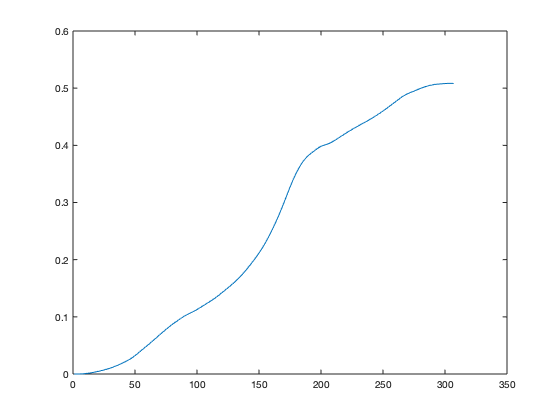

plot(dinteg_ofi(acc,100));